# Anomaly Detection

## Goals

- **Anomaly Detection:** Describe what anomaly detection is and its importance.

- **Sampling and Data Comparison Methods:** We present two approaches for anomaly detection, both of which leverage the speed and flexibility of surrogate models. 

- **Walk-Through:** Offer a simple, step-by-step guide of an example using both approaches.

## High-Level Highlights

Quickly detecting anomalous events is essential for safety-critical or highly optimized systems. Anomalous events may give the first indication of a system fault, failure, or mode change. We present two methods for computing confidence levels of a model's output. When used effectively, confidence levels can help you determine when an anomalous event occurs, thereby enhancing the safety and efficiency of systems. The plot below shows the result of the sampling method, a confidence curve of a system's output. Both methods leverage the flexibility and speed of surrogate models to produce confidence curves quickly and robustly. 

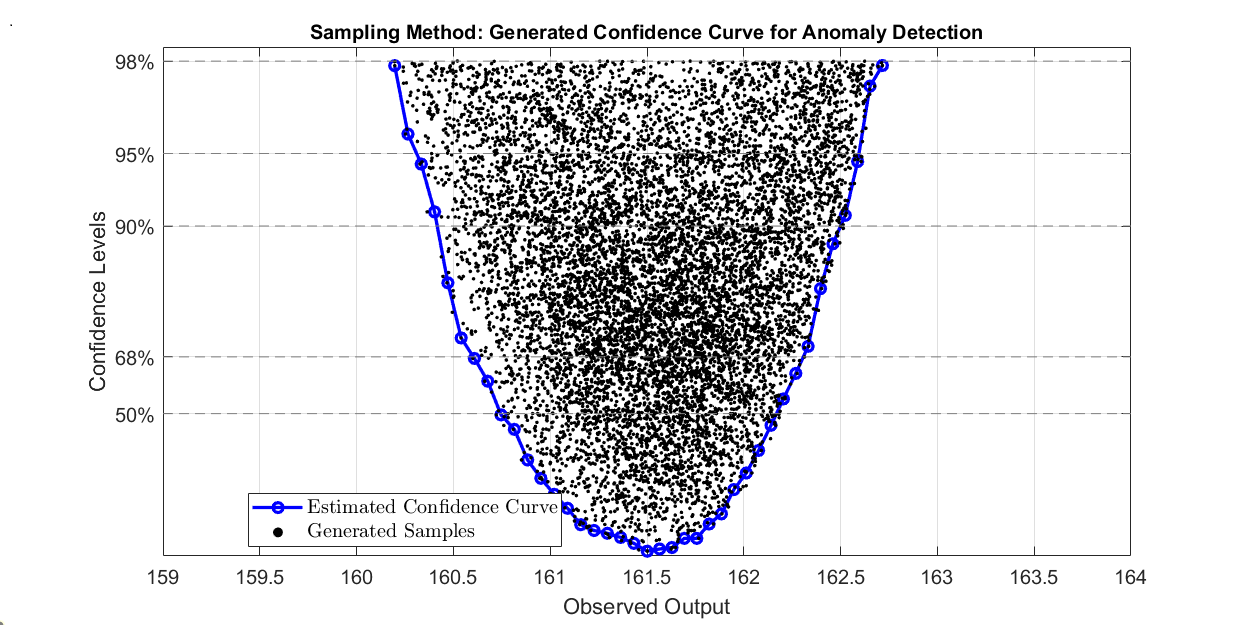

## Anomaly Detection

As noted in Optimization Under Uncertainty, some inputs to a simulation model may not be fully known or controlled. The values of these parameters are typically estimated or tuned to ensure the simulation model is accurate. However, any uncertainty in model parameters will cause uncertainty in the model's output. In Optimization Under Uncertainty, we used confidence bounds to establish system performance predictions under uncertainty. Given some confidence level, we can establish the range of expected system output.

Anomaly detection is a natural extension of this analysis. It determines when the system's behavior falls outside the expectation, that is, when the simulation model fails to predict the observed behavior. Detecting anomalous events is vital for autonomous systems or any tightly controlled system since accurate predictions are necessary for model-based actions and decisions. Furthermore, an anomalous event can be caused by a system failure, fault, or mode change. Therefore, anomaly detection may be the first step in uncovering a more significant issue with the system. 

Understanding the concept of confidence levels is key to implementing anomaly detection. In the previous section, we presented a plot that displays the computed confidence levels of a system's output. These levels help us establish the expected value of the system's output. Any values that fall outside of this range would be considered anomalous, indicating a deviation from the system's expected behavior. 

## Known and Uncertain Variables

In Surrogate Model-Based Optimization, we established the difference between decision and fixed variables. Here, we introduced a similar classification of model inputs: known and uncertain variables. Known variables are inputs to the model that are assumed to be perfectly known—for example, control parameters such as motor speeds or actuator voltages. Uncertain variables are inputs to the model that need to be estimated or are not completely known. Therefore, we cannot establish the exact values of these variables. However, as seen in Optimization Under Uncertainty, we can compute ranges of their possible values. As discussed in Surrogate Model-Based Optimization, the union of $x_{\text{known}}$ and $x_{\text{uncertain}}$ must equal the complete input set of the model. Therefore, an input to the model is either known or uncertain. In the context of surrogate models:

$\text{surrogate}(x) = \text{surrogate}(x_{\text{known}},x_{\text{uncertain}})}

$.

Note that the surrogate model's output will be uncertain since the uncertain variables, $x_{\text{uncertain}}$, can take a range of values. The following sections will present two approaches to computing confidence levels for the surrogate's output. 

## Sampling Approach 

The sampling approach utilizes the parameter estimation confidence levels from Parameter Estimation via Profile Likelihoods. We start by estimating the parameter via profile likelihood, enabling us to compute the confidence levels of various parameter configurations. Similar to Optimization Under Uncertainty, we consider the set of all possible uncertain variable values for a given confidence level $
\alpha$,    


$$P_\alpha = \{ x_\text{uncertain}^1,x_\text{uncertain}^2,\dots.\}.

$$


We will approximate the infinite set $P_\alpha


$ with a finite set $\bar{P}_\alpha$,


$$\bar{P}_\alpha = \{ x_\text{uncertain}^1,x_\text{uncertain}^2,\dots x_\text{uncertain}^n\}.

$$
 

The finite set $\bar{P}_\alpha

$ is constructed by iteratively computing the likelihoods of randomly generated sets of fixed variables. Any $x_\text{uncertain}^i

$  that achieves a minimal likelihood (based on the selected confidence level $
\alpha$ and the number of uncertain variables [1]) is placed into the set $\bar{P}_\alpha

$. The process is repeated in a loop until $\bar{P}_\alpha

$ is of the desired size. The likelihoods of $x_\text{uncertain}^i

$ are also recorded in $\bar{S}_\alpha

$. 

Next, a set of inputs to the surrogate model can be created by augmenting the members of $\bar{P}_\alpha

$ with a known input, $x_{\text{known}}$:  


$$X = \{ (x_\text{known}, x_\text{uncertain}^1),(x_\text{known}, x_\text{uncertain}^2),\dots (x_\text{known}, x_\text{uncertain}^n)\}.

$$


All members of $\bar{P}_\alpha

$ are augmented with the same $x_{\text{known}}$ since confidence bounds are computed at a specific operating point. The surrogate model is evaluated over all $X

$: 

$\text{surrogate}(X) = Y = \{y_1,y_2,\dots,y_n\}

$.

The sets $Y
$and $\bar{S}_\alpha

$, likelihoods computed during the creation of $\bar{P}_\alpha

$, are used to calculate confidence levels of the surrogate model output. The plot below visualizes the approach. Note that the accuracy of the estimate confidence curve will increase with more samples. If the system's operating point changes, we repeat the process to compute confidence levels at the new operating point.

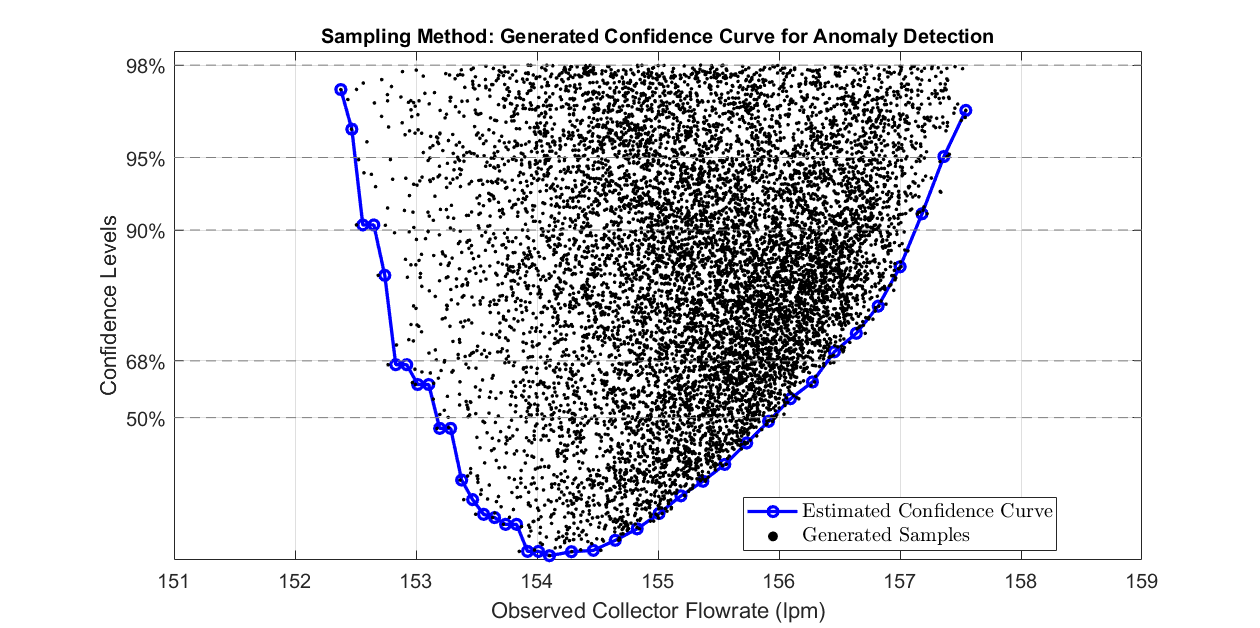

This approach is feasible due to the efficiency and flexibility of surrogate models. The Results section demonstrates that the surrogate model can evaluate a batch of tens of thousands of points in less than a second.

## Data Comparison Approach

This approach uses stored/historical data to determine the confidence levels of future outputs. Values of the unknown modeling parameters are estimated from the stored data by maximizing the likelihood function. We then redo the same estimation process while enforcing an additional constraint that the output of the surrogate model equals a selected value. Like constructing profile likelihood curves, the difference between the two likelihood values determines the confidence level of observing the selected value. Recall from Parameter Estimation via Profile Likelihoods that profile likelihood curves of unknown parameters were constructed by maximizing the likelihood function for each parameter of interest while holding a single parameter fixed at specific values. For this approach, we hold a single output fixed at specific values while maximizing the likelihood function. 

The plot below compares the sampling approach to the data comparison approach. It's important to note that the data sampling approach approximates the data comparison approach. However, the data comparison approach stands out for its scalability, as it doesn't rely on generating samples over a parameter space. In contrast, the sampling approach can quickly become unmanageable as the number of parameters increases. As demonstrated in Surrogate Model-Based Optimization, the data comparison approach is efficient for larger systems since it utilizes an optimization algorithm for parameter estimations. Furthermore, as shown in Surrogate Model-Based Optimization, optimization methods outperform Monte Carlo-based methods as the dimension of the system increases. 

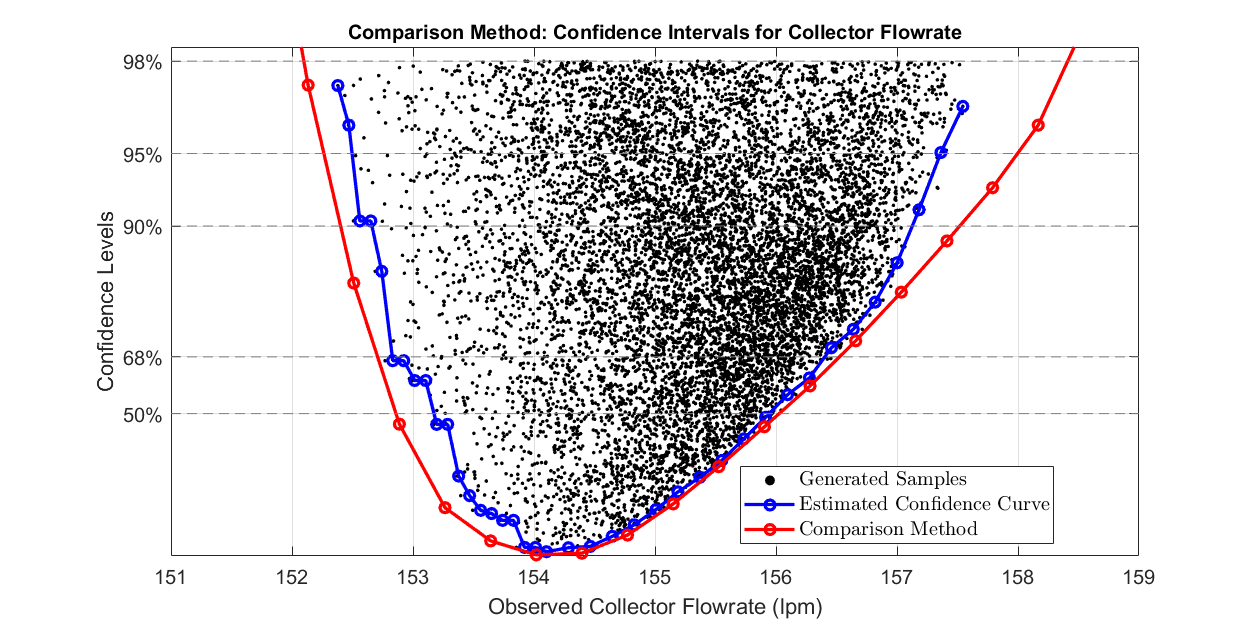

## Sensor Noise

Both methods can be modified to include sensor noise in the computed confidence levels. In the sampling approach, set $Y
$ is modified to add sensor noise to the surrogate model output. Moreover, the optimization constraint in the data comparison approach can be relaxed to include sensor noise.

## Example: Sampling Approach

In this section, we walk through an example to compute the confidence levels of an output of a system. We will use the small-scaled water pumping network described in Basics of Surrogate Model Creation. Our goal is to determine confidence levels for the observed collector flow rate.  

### Step 1: Estimate Unknown Model Parameters

First, we perform the parameter estimation procedure detailed in Parameter Estimation via Profile Likelihoods. The procedure results in estimates and confidence levels for all four source pressures. Source pressure is uncertain for this system since it is not directly controlled or observed. The confidence levels will be used to construct a set $\bar{P}_\alpha

$ in the following step.

The GUI Interface is described in detail in Parameter Estimation via Profile Likelihoods. For this example, we assume the collector flowmeter to be active. The user can select which pressure sensors are active.  

numSamples = 10;
disp('Active Sensors:')

Active Sensors:


disp('Collector Flowmeter is Active')

Collector Flowmeter is Active


collector_flowrate = true;
line_1_pressure = true;
line_2_pressure = true;
line_3_pressure = true;
line_4_pressure = true;
disp('Sensor Noise:')

Sensor Noise:


collector_flowrate_sigma = 0.75;
line_1_pressure_sigma = 0.1;
line_2_pressure_sigma = 0.3;
line_3_pressure_sigma = 0.1;
line_4_pressure_sigma = 0.2;

outputIdx = [];
sigma = [];
if collector_flowrate
    outputIdx(end+1) = 1;
    sigma(end+1) = collector_flowrate_sigma;
end
if line_1_pressure
    outputIdx(end+1) = 3;
    sigma(end+1) = line_1_pressure_sigma;
end
if line_2_pressure
    outputIdx(end+1) = 6;
    sigma(end+1) = line_2_pressure_sigma;
end
if line_3_pressure
    outputIdx(end+1) = 9;
    sigma(end+1) = line_3_pressure_sigma;
end
if line_4_pressure
    outputIdx(end+1) = 12;
    sigma(end+1) = line_4_pressure_sigma;
end

 

%% Generate Random Pressures to Estimate
sp = rand(4,1).*[0.8;0.8;0.8;0.8] + [0.6;0.6;0.6;0.6];
source_pressure.source_pressure_1 = sp(1);
source_pressure.source_pressure_2 = sp(2);
source_pressure.source_pressure_3 = sp(3);
source_pressure.source_pressure_4 = sp(4);

disp('Randomly select source pressures:')

Randomly select source pressures:


disp(['Source 1-4 Pressures (atm): ' num2str(source_pressure.source_pressure_1,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_2,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_3,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_4,'%.2f')])

Source 1-4 Pressures (atm): 1.18, 1.19, 0.84, 1.00


Executing parameter estimation...
Generating Profile Curve for Source Pressure 1
Generating Profile Curve for Source Pressure 2
Generating Profile Curve for Source Pressure 3
Generating Profile Curve for Source Pressure 4
A total of 32778 surrogate model evaluations were executed.
Sensor readings from 10 operational points were used in this analysis.


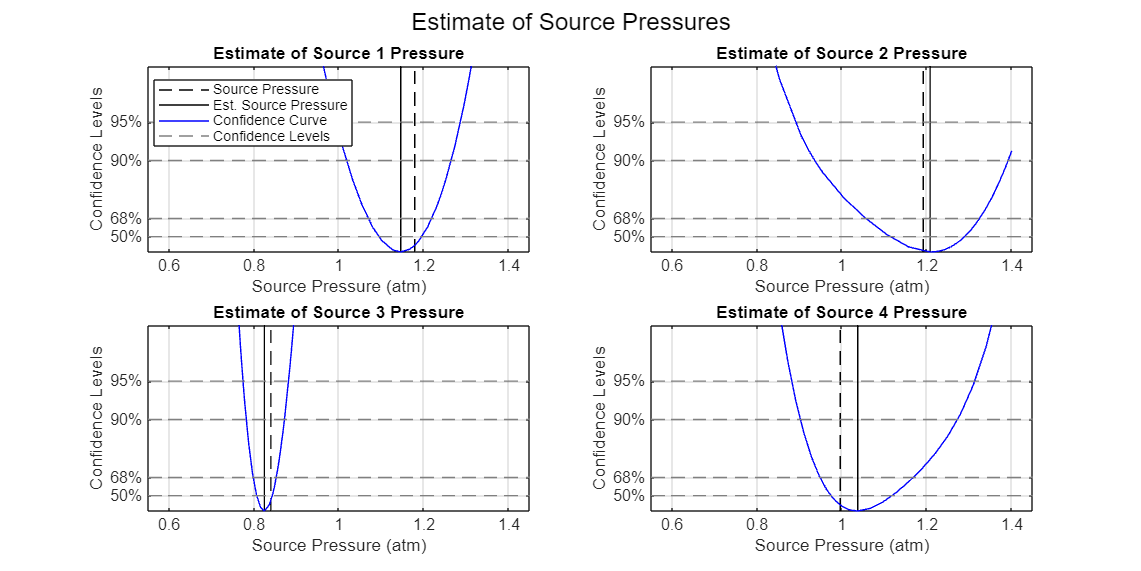


% Add path
addpath("./Surrogate Models")
addpath("./Utilities/")
addpath("Parameter Estimation\")

% Load Surrogate Model
if ~exist('parameter_small_mlp','var')
    load('./Surrogate Models/small_model.mat');
end

% Get random inputs and sensor readings
x = getRandomInputs(source_pressure,numSamples);
samples_ = small_scale_inference(x, parameter_small_mlp);
knownInputs = x([1,2:2:8],:); %extract collector pressure and pump speeds
sensorReadings = samples_(:,outputIdx) + randn(size(samples_,1),numel(outputIdx)).*sigma; % noise-up sensor readings

if isempty(outputIdx)
    disp('Select at least one sensor to use.')
else
    
    [V,S] = profileLikelihood(knownInputs,sensorReadings,source_pressure,outputIdx,sigma);
end

### Step 2: Compute Source Pressure Set

Once we compute the confidence intervals, a set $\bar{P}_\alpha

$ can be constructed. A set of the specified size is computed in which members fall within the specified confidence level. We plot the gathered set for visual inspection.

sizeSet = 10000;
confidenceLevel = 0.98;
 

%Use confidence bounds to determine search bounds
mins = zeros(4,1);
maxs = zeros(4,1);
for idx = 1:4
    %remove any non-unique scores and interpolate over a grid
    [V_,IA] = unique(round(V(:,idx),4));
    S_ = S(IA,idx)-min(S(:,idx))-chi2inv(confidenceLevel,1);
    [S_,IA] = unique(round(S_,4));
    V_ = V_(IA);
    [v,I] = sort(V_);
    s = S_(I);
    grid_v = 0.6:0.001:1.4;
    grid_scores = interp1(v,s,0.6:0.001:1.4,[],1.0);
    mins(idx) = min(grid_v(grid_scores<0));
    maxs(idx) = max(grid_v(grid_scores<0));
end

% Set \bar{P}_\alpha
randSample = zeros(sizeSet,4);
randScores = zeros(sizeSet,1);
idx = 1;
while 1
    randS = rand(10000,4).*(maxs'-mins') + mins';
    s = getScore(randS,parameter_small_mlp,knownInputs,sensorReadings',sigma,outputIdx) - min(S,[],'all');
    newidx = sum(s<chi2inv(confidenceLevel,4));
    randSample(idx:idx+newidx-1,:) = randS(s<chi2inv(confidenceLevel,4),:);
    randScores(idx:idx+newidx-1) = s(s<chi2inv(confidenceLevel,4));
    idx = idx + newidx;
    if idx>sizeSet
        break
    end
end
disp(['Set of size ' num2str(sizeSet) ' and confidence level ' num2str(confidenceLevel) ' generated!'])

Set of size 10000 and confidence level 0.98 generated!


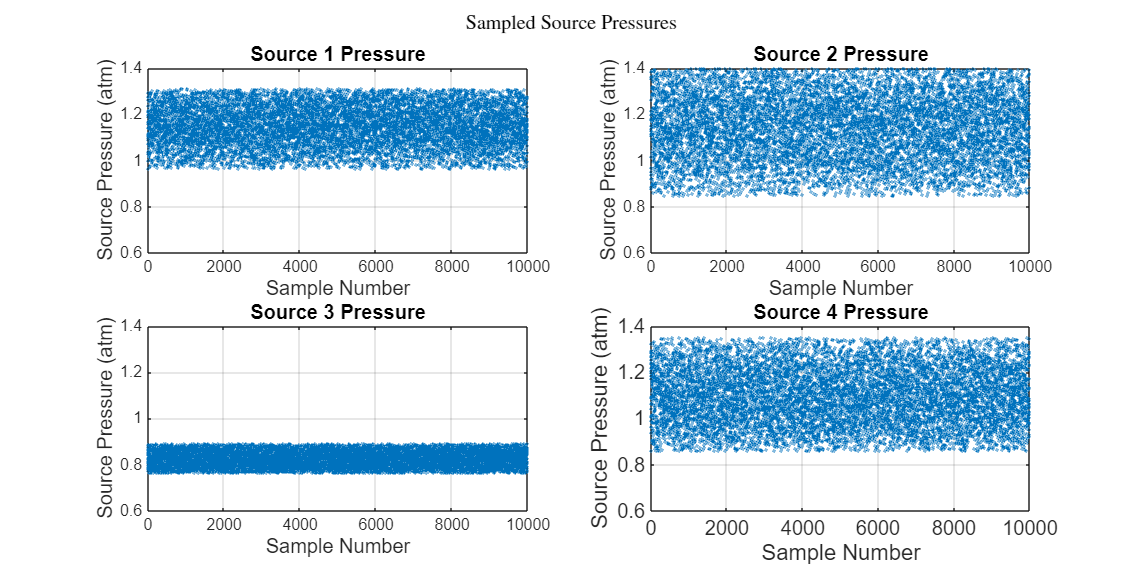

randSample = randSample(1:sizeSet,:);
randScores = randScores(1:sizeSet);

figure
set(gcf, 'Position', [100, 100, 1000, 500])
for idx = 1:4
    subplot(2, 2, idx);
    scatter(1:sizeSet,randSample(:,idx), 2)
    ylim([0.6,1.4])
    title(['Source ' num2str(idx) ' Pressure'],'FontSize',12);
    xlabel('Sample Number','FontSize',12);
    ylabel('Source Pressure (atm)','FontSize',12);
    box on 
    grid on
end 
sgtitle('Sampled Source Pressures','interpreter','latex','FontSize',12);
hAx = gca;
hAx.XAxis.FontSize = 12;
hAx.YAxis.FontSize = 12;

### Step 3: Determine Confidence Intervals of Collector Flowrate

The water pumping network has five known variables: the collector pressure and the pumping speed for each line. Once the operating point is defined, we evaluate the surrogate model at each member of the generated set $\bar{P}_\alpha

$. We sort the resulting outputs by their value and the likelihood of the associated uncertain variables. Once sorted, the estimated confidence levels of the modeling output can be computed. The plot below visualizes the process's final result. 

The workflow can incorporate the sensor noise of the observed output, including sensor noise results in broader confidence bounds to accommodate the larger range of possible (noisy) outputs. 

In the GUI below, the user can define the operating point and select between different plotting options. 

plotSamples = true;
includeSensorNoise = false;
disp('System Operating Point to Test:')

System Operating Point to Test:


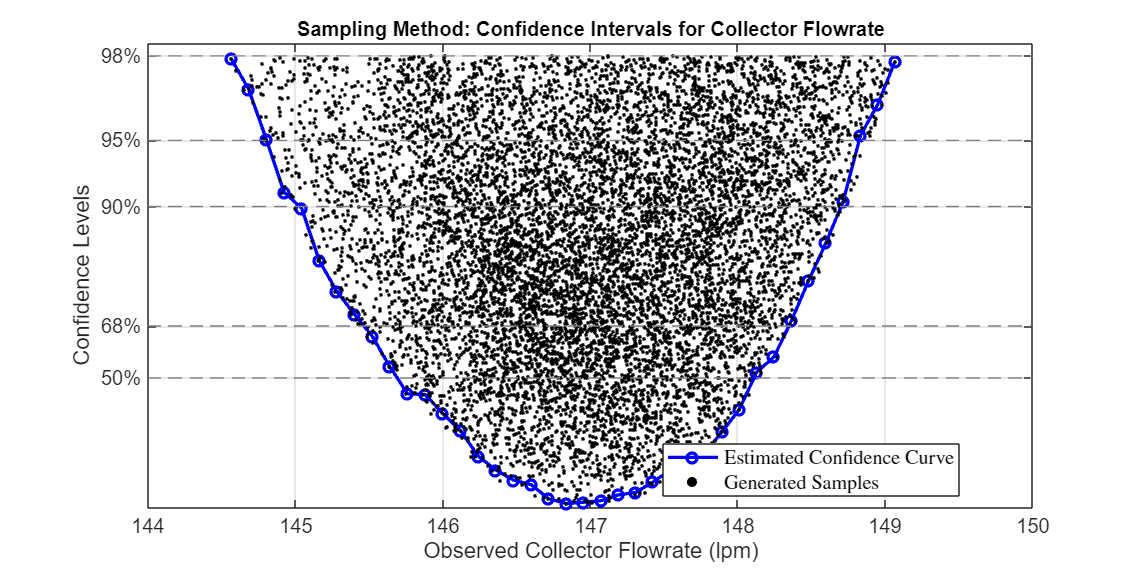

collectorPressure = 1.5;
line1Pumpspeed = 2450;
line2Pumpspeed = 2450;
line3Pumpspeed = 2450;
line4Pumpspeed = 2450;
 

if includeSensorNoise
    sensorError_flowrate = norminv(1-(1-confidenceLevel)/2,0,sigma(1));
else
    sensorError_flowrate = 0;
end

testInpt = [collectorPressure,line1Pumpspeed,line2Pumpspeed,line3Pumpspeed,line4Pumpspeed]';
x = completeInput(randSample,testInpt);
y_= small_scale_inference(x,parameter_small_mlp);
randFlowrates = y_(:,1);

% Sampling Based Method
[M,I] = min(randScores);
min_flowrate = randFlowrates(I);
bestScores = zeros(40,1);

lp_flowrate = linspace(min(randFlowrates),min_flowrate,20);
sampleFlowRates = lp_flowrate-sensorError_flowrate;
for ii = 1:numel(lp_flowrate)
    bestScores(ii) = min(randScores(randFlowrates<=lp_flowrate(ii)));
end
lp_flowrate = linspace(min_flowrate,max(randFlowrates),20);
for ii = 1:numel(lp_flowrate)
    bestScores(ii+20) = min(randScores(randFlowrates>=lp_flowrate(ii)));
end
sampleFlowRates= [sampleFlowRates,lp_flowrate+sensorError_flowrate];

fig = figure;
set(gcf, 'Position', [100, 100, 1000, 500])
hold on
plot(sampleFlowRates,bestScores,'b-o','LineWidth',2)
if plotSamples
    scatter(randFlowrates, randScores, 5,'k','filled','o')
end
if includeSensorNoise
    title('Sampling Method: Confidence Intervals for Noisy Collector Flowrate Measurements', 'FontSize',12);
else
    title('Sampling Method: Confidence Intervals for Collector Flowrate', 'FontSize',12);
end
xlabel('Observed Collector Flowrate (lpm)','FontSize',12);
ylabel('Confidence Levels','FontSize',12);
xfrlims = [floor(min(sampleFlowRates)-0.5), ceil(max(sampleFlowRates)+0.5)];
plot(xfrlims,[chi2inv(0.98,4), chi2inv(0.98,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.95,4), chi2inv(0.95,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.9,4), chi2inv(0.9,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.68,4), chi2inv(0.68,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.5,4), chi2inv(0.5,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])    
ylim([0,12])
xlim(xfrlims)
yticks([chi2inv(0.50,4),chi2inv(0.68,4),chi2inv(0.9,4),chi2inv(0.95,4),chi2inv(0.98,4)]);
yticklabels({'50%', '68%', '90%', '95%', '98%'});
box on 
grid on
if plotSamples
    legend(['Estimated Confidence Curve'],...
            ['Generated Samples'],...
            'FontSize',12,'Location','best','interpreter', 'latex');
else
    legend(['Estimated Confidence Level'],...
            'FontSize',12,'Location','best','interpreter', 'latex');
end
hAx = gca;
hAx.XAxis.FontSize = 12;
hAx.YAxis.FontSize = 12;

## Example: Data Comparison Approach

We walk through the same example as in the previous section. 

### Step 1: Collect Historical Data and Estimate Unknown Parameters

First, we perform the parameter estimation procedure detailed in Parameter Estimation via Profile Likelihoods. The procedure results in estimates and confidence levels for all four source pressures. Source pressure is uncertain for this system since it is not directly controlled or observed. The confidence levels will be used to construct a set $\bar{P}_\alpha

$ in the following step.

The GUI Interface is described in detail in Parameter Estimation via Profile Likelihoods. For this example, we assume the collector flowmeter to be active. The user can select which pressure sensors are active.  

numSamples = 10;
disp('Active Sensors:')

Active Sensors:


disp('Collector Flowmeter is Active')

Collector Flowmeter is Active


collector_flowrate = true;
line_1_pressure = true;
line_2_pressure = true;
line_3_pressure = true;
line_4_pressure = true;
disp('Sensor Noise:')

Sensor Noise:


collector_flowrate_sigma = 0.75;
line_1_pressure_sigma = 0.2;
line_2_pressure_sigma = 0.2;
line_3_pressure_sigma = 0.2;
line_4_pressure_sigma = 0.2;

outputIdx = [];
sigma = [];
if collector_flowrate
    outputIdx(end+1) = 1;
    sigma(end+1) = collector_flowrate_sigma;
end
if line_1_pressure
    outputIdx(end+1) = 3;
    sigma(end+1) = line_1_pressure_sigma;
end
if line_2_pressure
    outputIdx(end+1) = 6;
    sigma(end+1) = line_2_pressure_sigma;
end
if line_3_pressure
    outputIdx(end+1) = 9;
    sigma(end+1) = line_3_pressure_sigma;
end
if line_4_pressure
    outputIdx(end+1) = 12;
    sigma(end+1) = line_4_pressure_sigma;
end

 

%% Generate Random Pressures to Estimate
sp = rand(4,1).*[0.8;0.8;0.8;0.8] + [0.6;0.6;0.6;0.6];
source_pressure.source_pressure_1 = sp(1);
source_pressure.source_pressure_2 = sp(2);
source_pressure.source_pressure_3 = sp(3);
source_pressure.source_pressure_4 = sp(4);

disp('Randomly select source pressures:')

Randomly select source pressures:


disp(['Source 1-4 Pressures (atm): ' num2str(source_pressure.source_pressure_1,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_2,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_3,'%.2f') ', '...
                                    num2str(source_pressure.source_pressure_4,'%.2f')])

Source 1-4 Pressures (atm): 0.76, 1.04, 1.18, 0.98


Executing parameter estimation...
Generating Profile Curve for Source Pressure 1
Generating Profile Curve for Source Pressure 2
Generating Profile Curve for Source Pressure 3
Generating Profile Curve for Source Pressure 4
A total of 35171 surrogate model evaluations were executed.
Sensor readings from 10 operational points were used in this analysis.


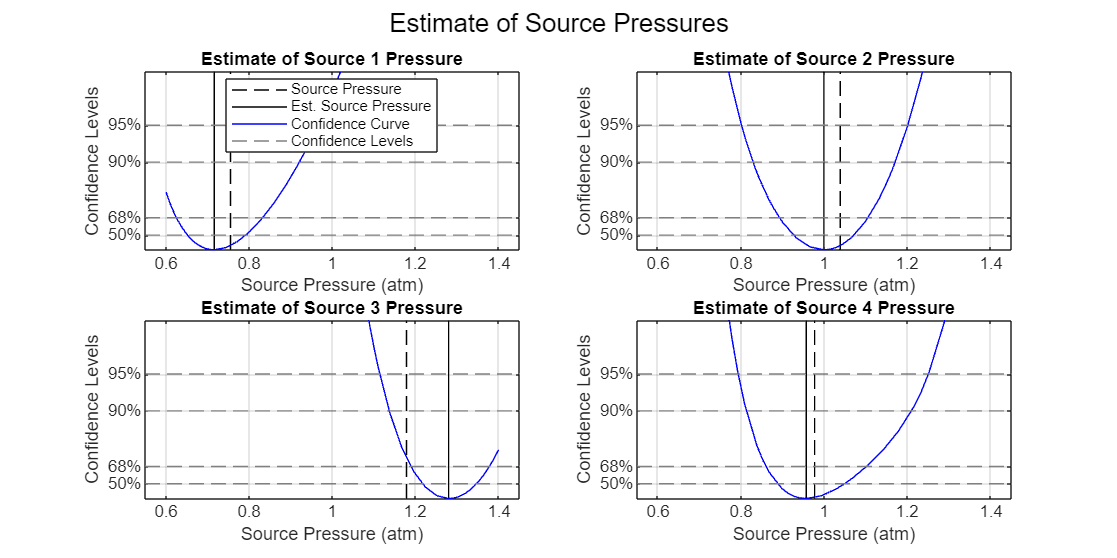


% Add path
addpath("./Surrogate Models")
addpath("./Utilities/")
addpath("Parameter Estimation\")

% Load Surrogate Model
if ~exist('parameter_small_mlp','var')
    load('./Surrogate Models/small_model.mat');
end

% Get random inputs and sensor readings
x = getRandomInputs(source_pressure,numSamples);
samples_ = small_scale_inference(x, parameter_small_mlp);
knownInputs = x([1,2:2:8],:); %extract collector pressure and pump speeds
sensorReadings = samples_(:,outputIdx) + randn(size(samples_,1),numel(outputIdx)).*sigma; % noise-up sensor readings

if isempty(outputIdx)
    disp('Select at least one sensor to use.')
else
    
    [V,S] = profileLikelihood(knownInputs,sensorReadings,source_pressure,outputIdx,sigma);
end

### Step 2: Compute the Profile Curve of the Output

We use the historical data generated in the previous step to compute a profile curve of future collector flow rates. 

The plot compares the two approaches. Note that the comparison approach gives wider confidence bounds since the sampling method approximates confidence levels. 

In the GUI below, the user can define the operating point, select between different plotting options, and set the sampling set for comparison.  

disp('Sample set for comparison to Sampling Method:')

Sample set for comparison to Sampling Method:


sizeSet = 10000;
disp('Plotting Options:')

Plotting Options:


plotSamples = true;
includeSensorNoise = false;
disp('Maximum Confidence Level:')

Maximum Confidence Level:


confidenceLevel = 0.98;
disp('System Operating Point to Test:')

System Operating Point to Test:


collectorPressure = 1.5;
line1Pumpspeed = 2750;
line2Pumpspeed = 2450;
line3Pumpspeed = 2850;
line4Pumpspeed = 2450;

 

%% Compare to Sample Approach
%Use confidence bounds to determine search bounds
mins = zeros(4,1);
maxs = zeros(4,1);
for idx = 1:4
    %remove any non-unique scores and interpolate over a grid
    [V_,IA] = unique(round(V(:,idx),4));
    S_ = S(IA,idx)-min(S(:,idx))-chi2inv(confidenceLevel,1);
    [S_,IA] = unique(round(S_,4));
    V_ = V_(IA);
    [v,I] = sort(V_);
    s = S_(I);
    grid_v = 0.6:0.001:1.4;
    grid_scores = interp1(v,s,0.6:0.001:1.4,[],1.0);
    mins(idx) = min(grid_v(grid_scores<0));
    maxs(idx) = max(grid_v(grid_scores<0));
end

% Set \bar{P}_\alpha
randSample = zeros(sizeSet,4);
randScores = zeros(sizeSet,1);
idx = 1;
while 1
    randS = rand(10000,4).*(maxs'-mins') + mins';
    s = getScore(randS,parameter_small_mlp,knownInputs,sensorReadings',sigma,outputIdx) - min(S,[],'all');
    newidx = sum(s<chi2inv(confidenceLevel,4));
    randSample(idx:idx+newidx-1,:) = randS(s<chi2inv(confidenceLevel,4),:);
    randScores(idx:idx+newidx-1) = s(s<chi2inv(confidenceLevel,4));
    idx = idx + newidx;
    if idx>sizeSet
        break
    end
end
randSample = randSample(1:sizeSet,:);
randScores = randScores(1:sizeSet);

if includeSensorNoise
    sensorError_flowrate = norminv(1-(1-confidenceLevel)/2,0,sigma(1));
else
    sensorError_flowrate = 0;
end

testInpt = [collectorPressure,line1Pumpspeed,line2Pumpspeed,line3Pumpspeed,line4Pumpspeed]';
x = completeInput(randSample,testInpt);
y_= small_scale_inference(x,parameter_small_mlp);
randFlowrates = y_(:,1);

%% Sampling Based Method
[M,I] = min(randScores);
min_flowrate = randFlowrates(I);
bestScores = zeros(40,1);

lp_flowrate = linspace(min(randFlowrates),min_flowrate,20);
sampleFlowRates = lp_flowrate-sensorError_flowrate;
for ii = 1:numel(lp_flowrate)
    bestScores(ii) = min(randScores(randFlowrates<=lp_flowrate(ii)));
end
lp_flowrate = linspace(min_flowrate,max(randFlowrates),20);
for ii = 1:numel(lp_flowrate)
    bestScores(ii+20) = min(randScores(randFlowrates>=lp_flowrate(ii)));
end
sampleFlowRates= [sampleFlowRates,lp_flowrate+sensorError_flowrate];

%% Comparison method
comparisonScore = zeros(20,1);
comparisonV = zeros(20,1);
tic
for idx = 1:20
    newFlowrate = (idx-1)/19*(max(sampleFlowRates+1)-min(sampleFlowRates-1)) + min(sampleFlowRates-1);
    newknownInputs_ = [collectorPressure,line1Pumpspeed,line2Pumpspeed,line3Pumpspeed,line4Pumpspeed]';
    [x_min, fvalmax, exit_flag] = comparisonAnomalyDetection(newknownInputs_,newFlowrate,...
                                                                knownInputs,sensorReadings,sigma,outputIdx,...
                                                                includeSensorNoise,confidenceLevel);
    if all(exit_flag==-2)
        % solution not found for the given confidence level
        comparisonScore(idx) = chi2inv(0.999,4);
    else
        comparisonScore(idx) = fvalmax - min(S,[],'all');    
    end
    comparisonV(idx) = newFlowrate;
end
caTime_ = toc;
disp(['Average time to execute data comparison approach: ' num2str(caTime_/20)]);

Average time to execute data comparison approach: 2.8849


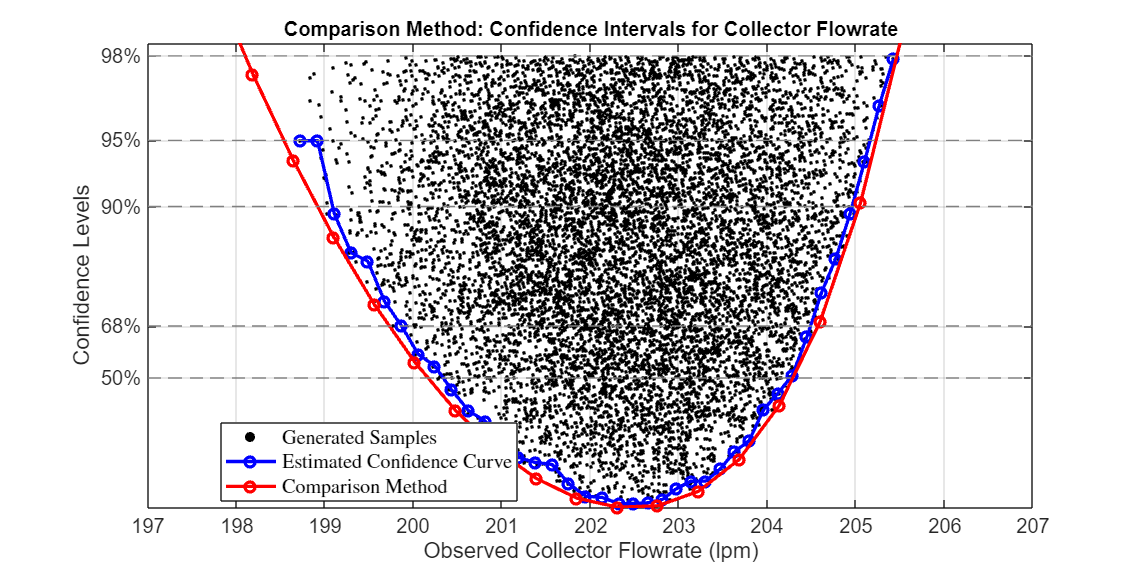


fig = figure;
set(gcf, 'Position', [100, 100, 1000, 500])
hold on
if plotSamples
    scatter(randFlowrates, randScores, 5,'k','filled','o')
end
plot(sampleFlowRates,bestScores,'b-o','LineWidth',2)
plot(comparisonV,comparisonScore, 'r-o','LineWidth',2)
if includeSensorNoise
    title('Comparison Method: Confidence Intervals for Noisy Collector Flowrate Measurements', 'FontSize',12);
else
    title('Comparison Method: Confidence Intervals for Collector Flowrate', 'FontSize',12);
end
xlabel('Observed Collector Flowrate (lpm)','FontSize',12);
ylabel('Confidence Levels','FontSize',12);
xfrlims = [floor(min(sampleFlowRates)-1.0), ceil(max(sampleFlowRates)+1.0)];
plot(xfrlims,[chi2inv(0.98,4), chi2inv(0.98,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.95,4), chi2inv(0.95,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.9,4), chi2inv(0.9,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.68,4), chi2inv(0.68,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])
plot(xfrlims,[chi2inv(0.5,4), chi2inv(0.5,4)],'--', 'color', [0.5, 0.5, 0.5, 0.5])    
ylim([0,12])
xlim(xfrlims)
yticks([chi2inv(0.50,4),chi2inv(0.68,4),chi2inv(0.9,4),chi2inv(0.95,4),chi2inv(0.98,4)]);
yticklabels({'50%', '68%', '90%', '95%', '98%'});
box on 
grid on
if plotSamples
    legend(['Generated Samples'],...
            ['Estimated Confidence Curve'],...
            ['Comparison Method'],...
            'FontSize',12,'Location','best','interpreter', 'latex');
else
    legend(['Estimated Confidence Level'],...
            ['Comparison Method'],...
            'FontSize',12,'Location','best','interpreter', 'latex');
end
hAx = gca;
hAx.XAxis.FontSize = 12;
hAx.YAxis.FontSize = 12;

## Results

### Speed

As mentioned above, both methods leverage the speed of surrogate models. In Basics of Surrogate Model Creation, we demonstrated that surrogate models are much faster than their physics-based counterparts. This speed advantage is magnified when model evaluations are executed in batches. In the GUI below, the surrogate model performs tens of thousands of evaluations in under a second. The sampling approach presented above heavily leverages a surrogate model's speed and flexibility. 

if ~exist('parameter_small_mlp','var')
    addpath("./Surrogate Models")
    load('./Surrogate Models/small_model.mat');
    disp("MLP parameters loaded.")
end

%Collection Parameters
sampled_name_list = ["collector_pressure"]; % parameter ID
lower_limit = [1]; % lower limit for sampling 
upper_limit = [1.5]; % upper limit for sampling

%Line 1-4 Parameters
for idx = 1:8
    sampled_name_list(end+1) = strcat("pump_speed_", int2str(idx));
    lower_limit(end+1) = 2450;
    upper_limit(end+1) = 3000;
    sampled_name_list(end+1) = strcat("source_pressure_", int2str(idx));
    lower_limit(end+1) = 0.5;
    upper_limit(end+1) = 1.5;
end

% Generate Random Samples for Small-Scale
numSamples = 41190;
X = rand(9,numSamples).*(upper_limit(1:9)' - lower_limit(1:9)') + lower_limit(1:9)';

tic
small_scale_inference(X,parameter_small_mlp);
batchTime_ = toc;
disp(['Total evaluation time for a Batch of '...
      num2str(numSamples) ' samples (s): ' num2str(batchTime_)]);

Total evaluation time for a Batch of 41190 samples (s): 0.087592


In addition, in Surrogate Model-Based Optimization, we demonstrated that surrogate models accelerated and robustified constrained optimization. We exploited these advantages when implementing the data comparison approach. Note that the second walk-through example shows that the comparison method only takes a few seconds to complete. Therefore, a real-time assessment of anomalous events is possible in more efficient and realistic deployments.  

### **Including Sensor Noise **

Since the observed output will be noisy, any anomaly detection algorithm should be able to incorporate sensor noise. The two plots below illustrate that both methods can do just that. The first plot displays the confidence curves when no sensor noise is considered. The second plot displays results when a sensor model of $$\mathcal{N}(0,0.75^2)$$ (lpm) is assumed for the collector flowmeter. 

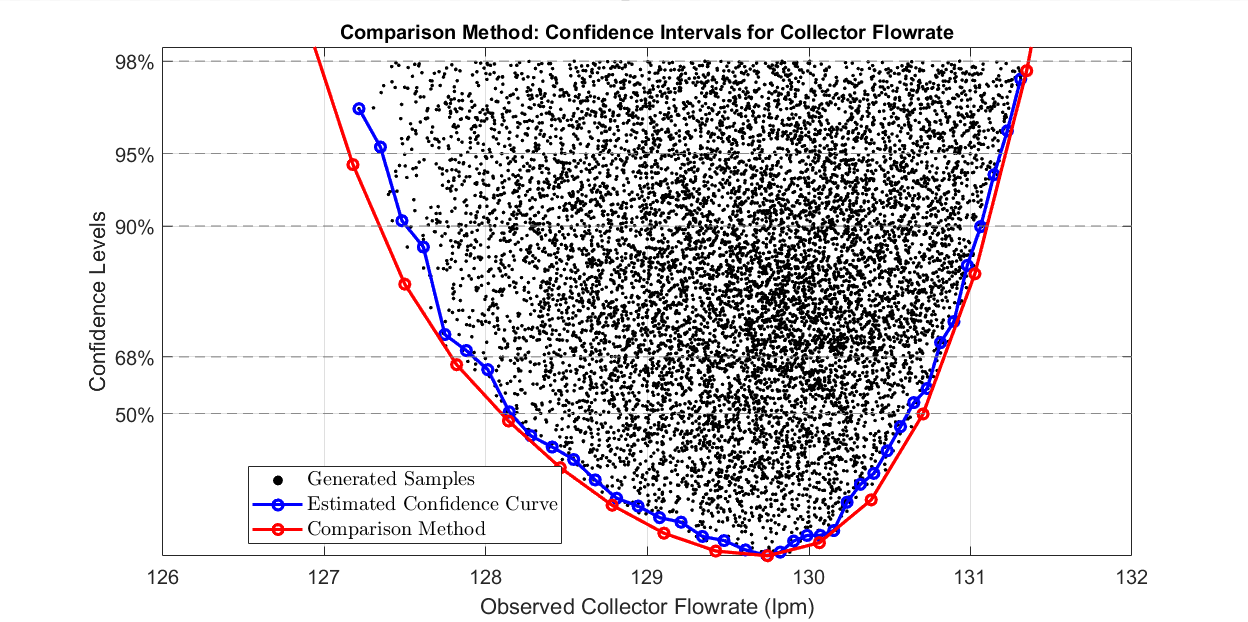

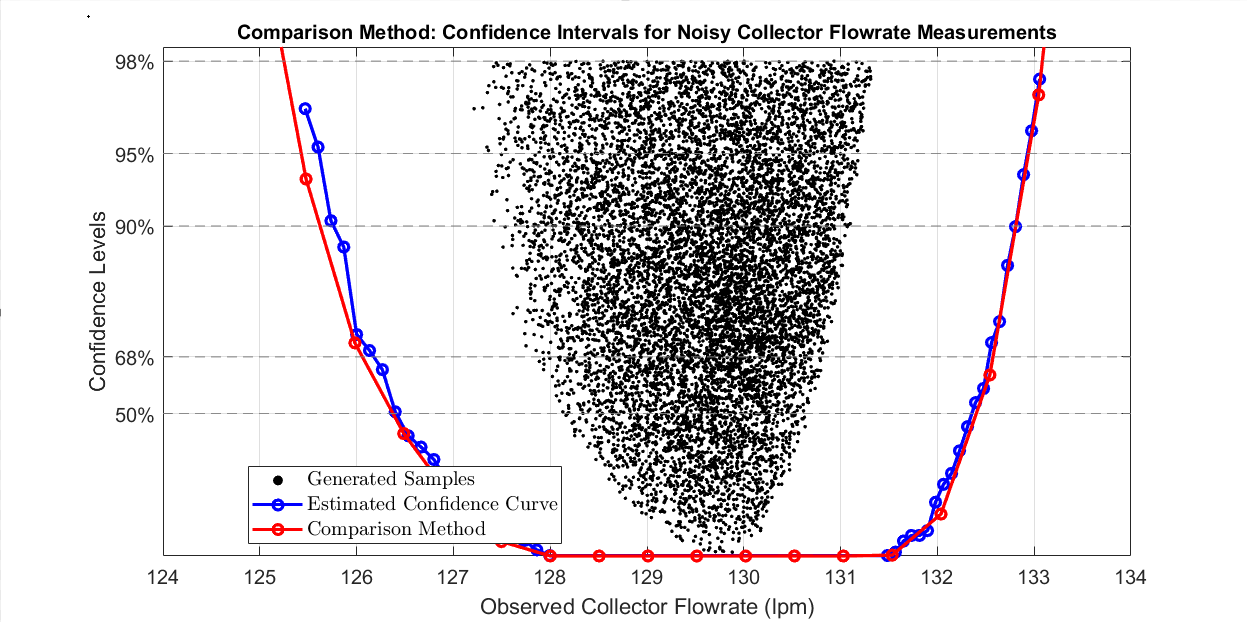

### **Sparse Samples**

Using sparse samples for the sampling methods reduces the accuracy of the approach. The data comparison approach is the correct path to achieving scalable results. However, the sampling approach remains implementable for small systems and is a great way to test the data comparison approach. The plot below compares the estimated confidence curve when 2,500 and 25,000 samples are available for confidence curve estimation. 

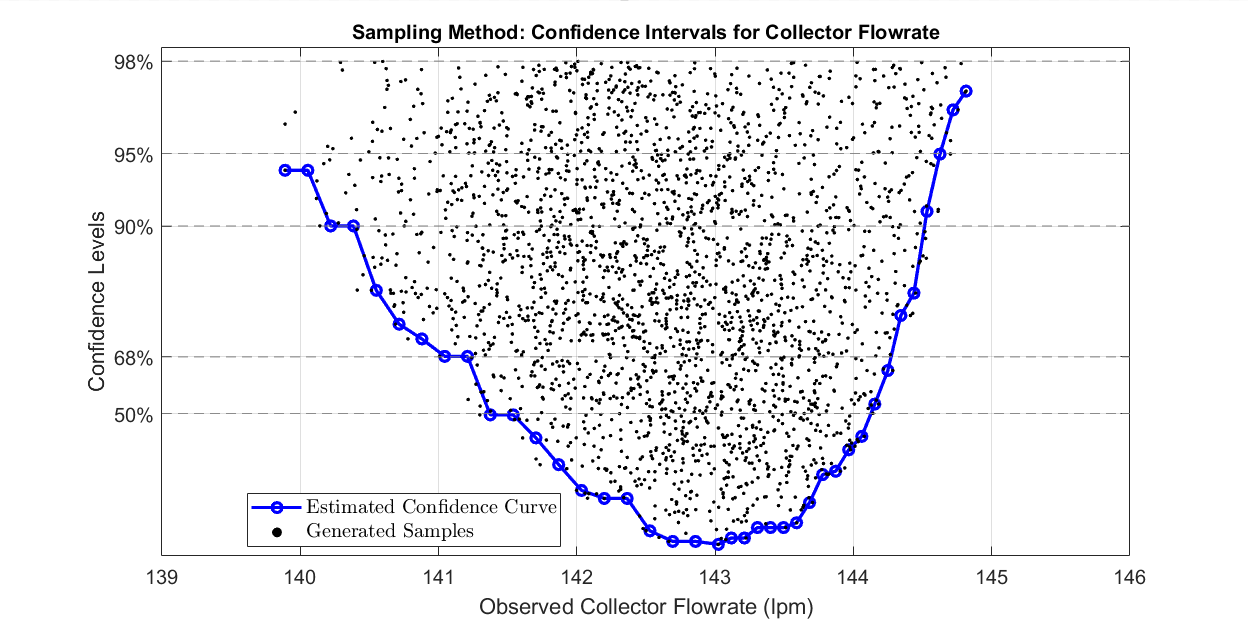

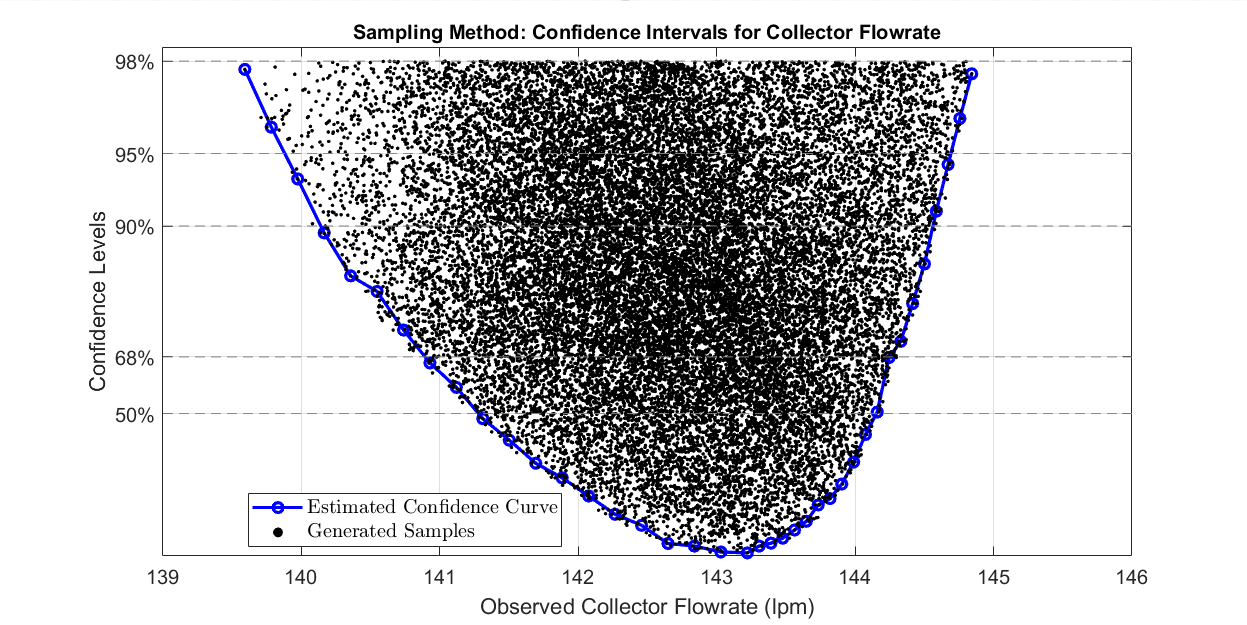

### **Asymmetrical Results**

Though most confidence levels are symmetrical, some are not. Asymmetrical results highlight the nonlinear nature of the underlying system. Instead of conducting rigorous analysis, operators may be tempted to add Gaussian noise to a physics-based model's output to account for uncertainty. However, asymmetrical results highlight the dangers of this simple approach. Furthermore, it is challenging to translate uncertainty in modeling parameters to uncertainty in modeling outputs without rigorous analysis. Therefore, adding Gaussian noise will likely overestimate or underestimate the uncertainty in the model's output.  

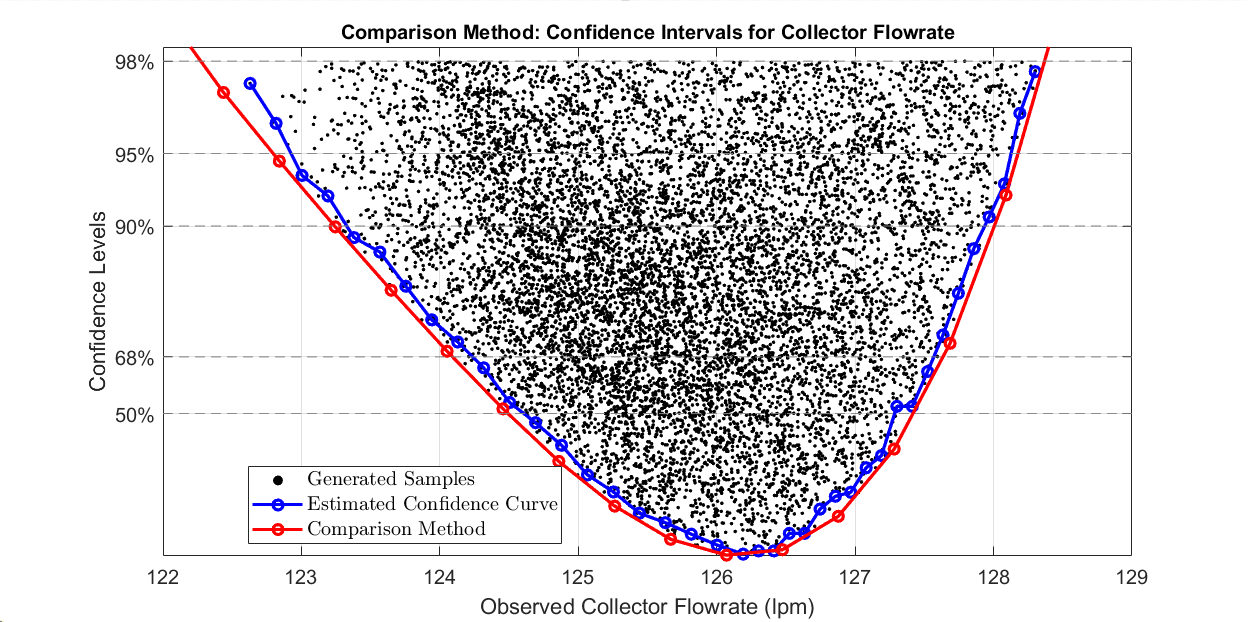

### **Multiple Outputs**

The methods presented above can be modified to include multiple outputs. The plot below displays the confidence levels for the collector flow rate and line 1 pressure. The 2-D confidence curves result in interesting relationships between the outputs and give a richer context for anomaly detection.

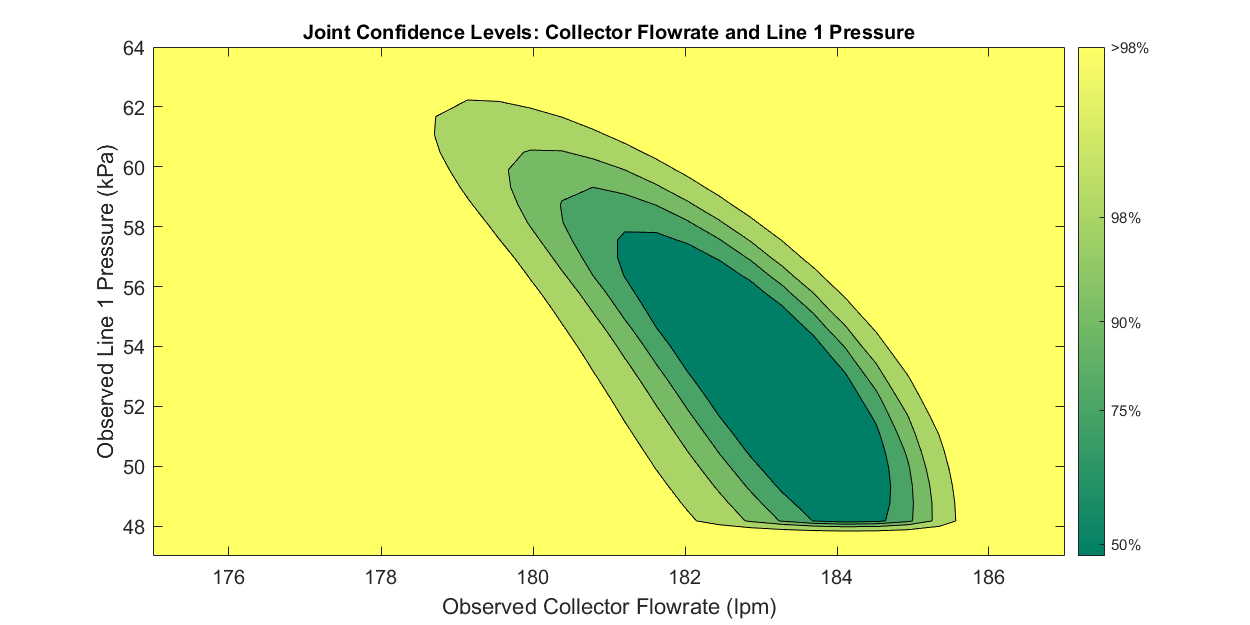

## Summary

Identifying anomalous events is vital for safety-critical or highly optimized systems. These events are often the first sign of a system fault, failure, or mode change. We have introduced two practical methods for computing the confidence levels of a model's output. An output's confidence levels determine the likelihood of anomalous events. Both methods leverage the flexibility and speed of surrogate models to produce confidence curves quickly and robustly.   

## References

- [Royston, Patrick. "Profile likelihood for estimation and confidence intervals." *The Stata Journal* 7.3 (2007): 376-387.](https://journals.sagepub.com/doi/pdf/10.1177/1536867X0700700305)